Simulation of ACh sensor that should go to the paper.

% give this simulation a name
SimulationName='simulation_ACh_20221220';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20221220/'

cd(filepath)

% load the file of ACh sensor under ACh 100 uM condition
spc_openCurves('/Users/pingchuanma/Desktop/ChenLab_Data/simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM108.mat')

Reading /Users/pingchuanma/Desktop/ChenLab_Data/simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM108.mat


load('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM108.mat')

% move the corresponding prf to this folder, load this prf and do the
% fitting
cd(filepath)
copyfile /Volumes/yaochen/Active/Pingchuan/prf/0903_prf_insight_pc.mat prf.mat

% after doing the fitting, output the fitting parameters

p1_ACh=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_ACh = 0.7622

p2_ACh=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_ACh = 0.2378

tau1_ACh=spc.fits{1,1}.beta2

tau1_ACh = 2.8006

tau2_ACh=spc.fits{1,1}.beta4

tau2_ACh = 0.1074

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.0780

SHG=spc.fits{1,1}.beta6

SHG = 0

samplesize_ACh=sum(spc.lifetimes{1})

samplesize_ACh = 833523

SHG_proportion=SHG/samplesize_ACh

SHG_proportion = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 1.8797

backcorr=spc.fits{1,1}.backCorr

backcorr = 124.2613


% calculate the empirical lifetime from the histogram, considering the
% first 8 and last 8 channels are forced to be 0, and considering the
% fitting range.
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     10   235


weight_n_lft=lft_steps.*spc.lifetimes{1}(range(1):range(2));
empirical_lft_ACh=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_ACh = 4.6452


% also export the histogram
n_exp_ACh=spc.lifetimes{1};


% lft_steps(1:8)=0;
% lft_steps(end-7:end)=0;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     10   235


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


weight_n_lft=lft_steps.*spc.lifetimes{1}(range(1):range(2));
empirical_lft_ACh=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_ACh = 4.6452


% calculate the empirical lifetime from the fitted curve


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


weight_n_lft=lft_steps.*spc.fits{1,1}.curve';
empirical_lft_ACh_curve=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_ACh_curve = 4.6382

% save the fitting parameters
save('fitting_parameters.mat','p1_ACh','p2_ACh','tau1_ACh','tau2_ACh','delta_peak_time','SHG','samplesize_ACh','backcorr','empirical_lft_ACh','empirical_lft_ACh_curve')

% adjust the prf based on the delta peak time
% comment more the what the interpolation does and why doing that

load('prf.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_ACh=find(prf_interp1==max(prf_interp1))

prf_peak_ACh = 54

find(prf==max(prf))

ans = 53

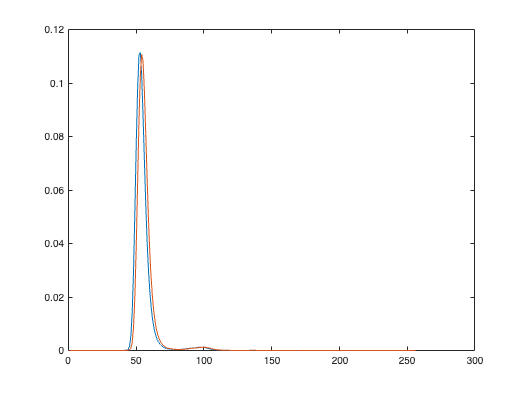


figure
plot(prf)
hold on
plot(prf_interp1)

% save this prf for future use
prf=prf_interp1;
prf_interp1_name='prf_ACh_interp1.mat';
save(prf_interp1_name,'prf')

% select a ROI or two, fix the offset at 0 for empirical lifetime
% find the corresponding functions to calculate the roi lifetime

global offset fixedoffset
fixedoffset=1;
offset=0;
spc_adjustTauOffset(1)

photoncount_ACh=gui.gy.ROIcount(1)

photoncount_ACh = 201910

photoncount_ACh_mean=gui.gy.ROImean(1)

photoncount_ACh_mean = 167.4212

lft=gui.gy.ROIlife(1)

lft = 4.7022

ROIsize_ACh=photoncount_ACh/photoncount_ACh_mean

ROIsize_ACh = 1206

% go to another file of baseline condition
spc_openCurves('/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM009.mat')

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20220722/0831HEKAchsensor003/0831HEKAchsensor003FLIM009.mat


% adjust the ROI position


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     10   235


weight_n_lft=lft_steps.*spc.lifetimes{1}(range(1):range(2));
empirical_lft_baseline=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_baseline = 4.5218

backcorr_baseline=spc.fits{1,1}.backCorr

backcorr_baseline = 14.9467


samplesize_baseline=sum(spc.lifetimes{1})

samplesize_baseline = 284979

n_exp_baseline=spc.lifetimes{1};


photoncount_baseline=gui.gy.ROIcount(1)

photoncount_baseline = 51745

photoncount_mean_baseline=gui.gy.ROImean(1)

photoncount_mean_baseline = 43.1208

lft_baseline=gui.gy.ROIlife(1)

lft_baseline = 4.5728

ROIsize_baseline=photoncount_baseline/photoncount_mean_baseline

ROIsize_baseline = 1200

% Name the population of double exponential decay
PopulationName='ACh_population_20221220'

PopulationName = 'ACh_population_20221220'

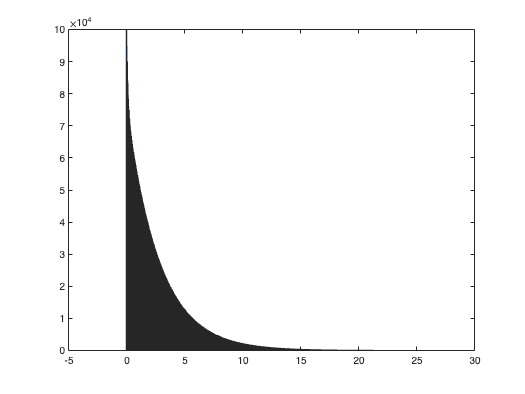

     4465438



% generate the double exponential population, no SHG added, 512 channels
GenPop512_Ach(100000,p1_ACh,p2_ACh,tau1_ACh,tau2_ACh,PopulationName)

% GenPop512_SHG_Ach(100000,p1_ACh,p2_ACh,tau1_ACh,tau2_ACh,PopulationNameSHG, SHG_proportion)

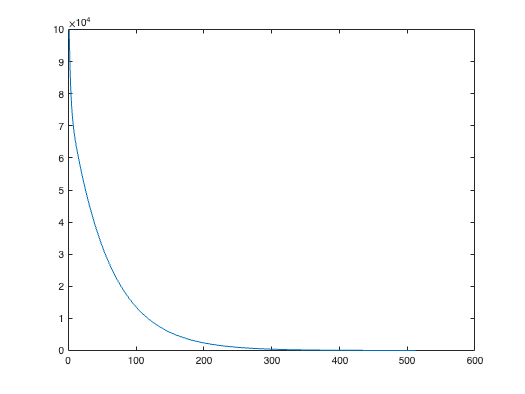

%% Test the population generated is ok. Calculate the analytical lft for each population

load(PopulationName)
xsim=linspace(0,25,512);
[n,xout]=hist(Population, xsim);
figure
plot(n)

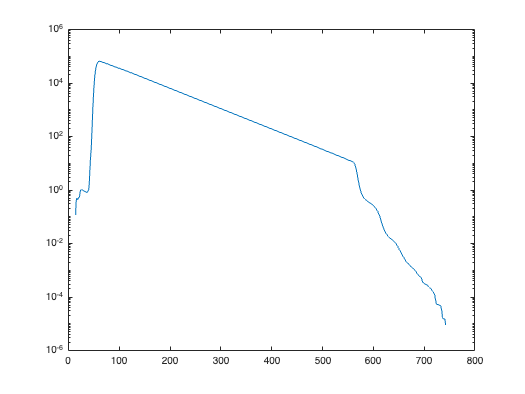


% convolute the double exponential curve use the new prf
conv_n=conv(n,prf);
figure % plot right after the convolution
semilogy(conv_n)

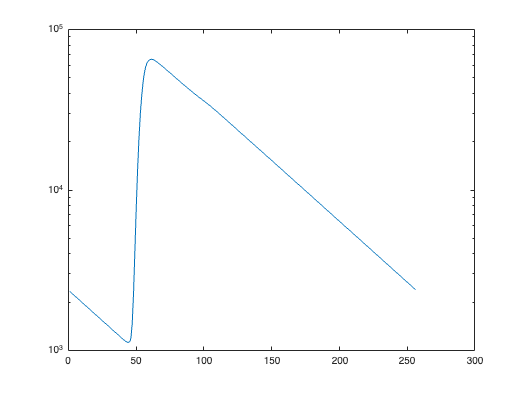


conv_n1=conv_n(257:512);
conv_n_final=conv_n(1:256)+conv_n1; % wrap around

figure
semilogy(conv_n_final) % plot after wrap around


% before background correction, calculate the empirical lifetime

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


weight_n_lft=lft_steps.*conv_n_final(range(1):range(2));
empirical_lft=sum(weight_n_lft)/sum(conv_n_final(range(1):range(2)))

empirical_lft = 4.6046


% add the background correction term, calculate the empirical lifetime
backcorr_ratio=backcorr/samplesize_ACh;
backcorr_ACh=sum(conv_n_final)*backcorr_ratio

backcorr_ACh = 665.5662

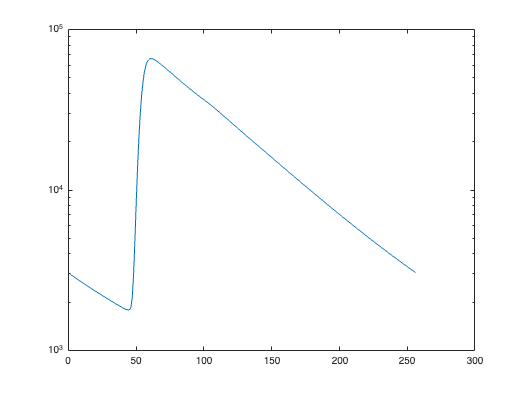

conv_n_final_corr=conv_n_final+backcorr_ACh;
figure
semilogy(conv_n_final_corr)

empirical_lft_PopNoSHG = 4.6357

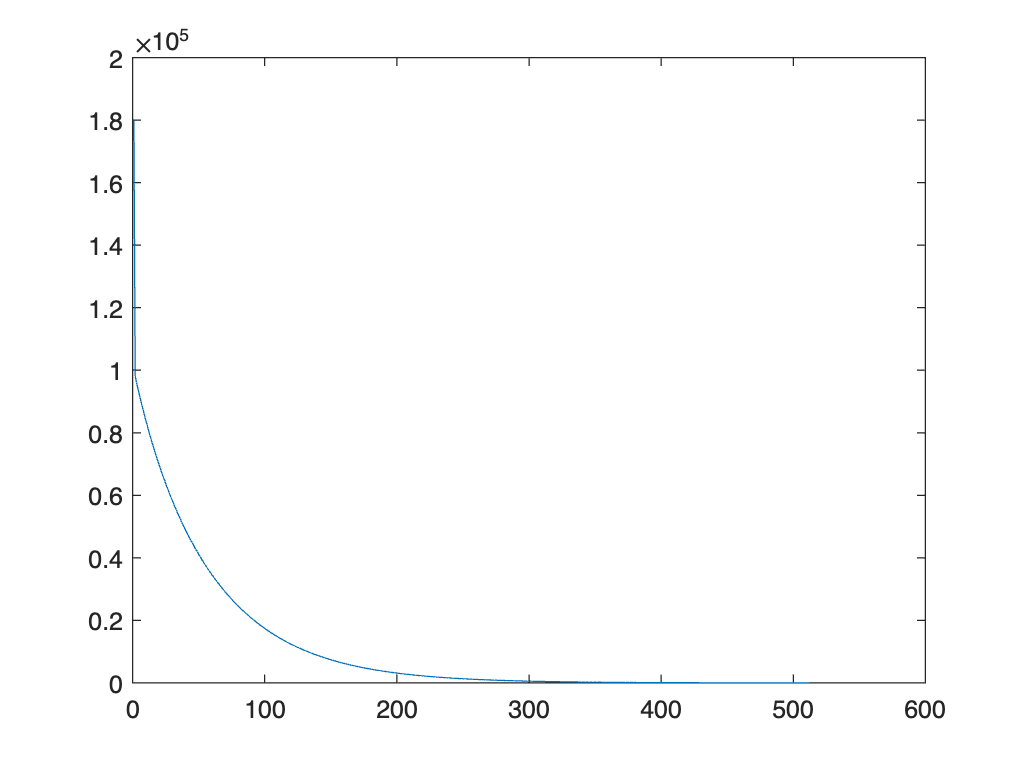

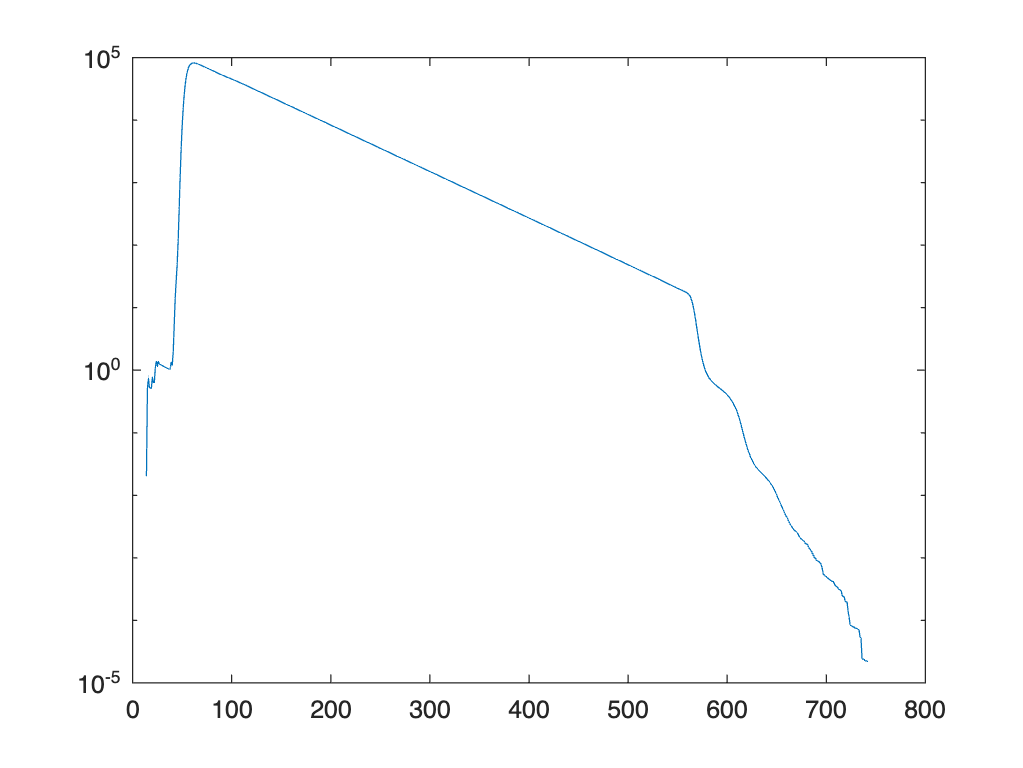

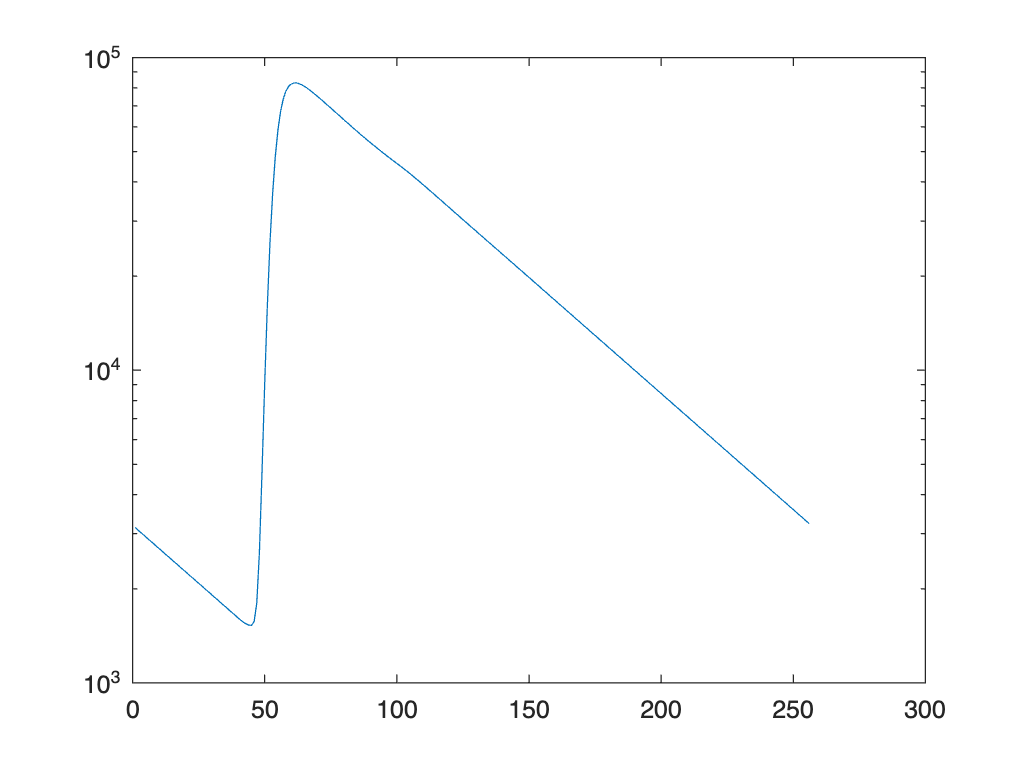

empirical_lft_PKA = 5.1376

backcorr_ACh = 730.4119

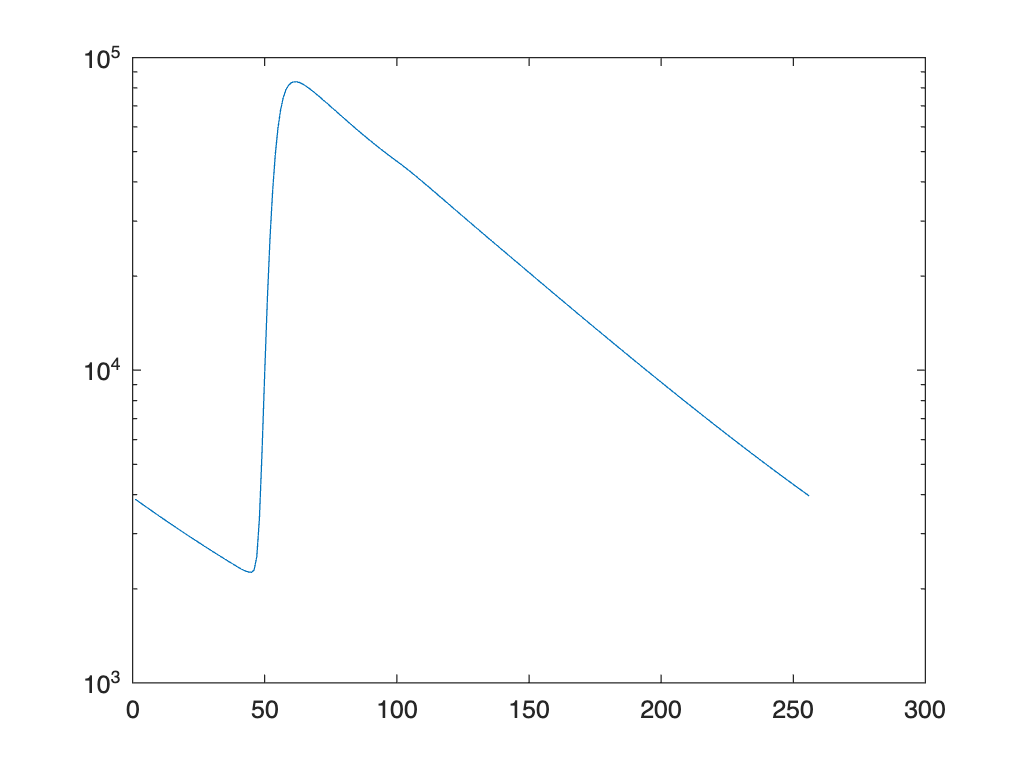

empirical_lft_PKA = 5.1762


% from the fitted curve: empirical_lft_ACh_curve = 5.1776
weight_n_lft=lft_steps.*conv_n_final_corr(range(1):range(2));
empirical_lft_PopNoSHG=sum(weight_n_lft)/sum(conv_n_final_corr(range(1):range(2)))

copyfile /Volumes/yaochen/Active/Pingchuan/simulation/AutoFluo0917.mat autofluorescence.mat

load('autofluorescence.mat')

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


weight_n_lft=lft_steps.*AutoFluo0917(range(1):range(2));
empirical_lft=sum(weight_n_lft)/sum(AutoFluo0917(range(1):range(2)))

empirical_lft = 4.0566

% test the simulation, if no dark count, no afterpulse, no
% autofluorescence, simulate and then add background correction, the
% lifetime should be similiar to the fitted curve
DC=0;
afterpulse=0;
AF=0;
SaveName='test_sim.mat'

SaveName = 'test_sim.mat'

FLIMsim512_Ach(samplesize_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName)

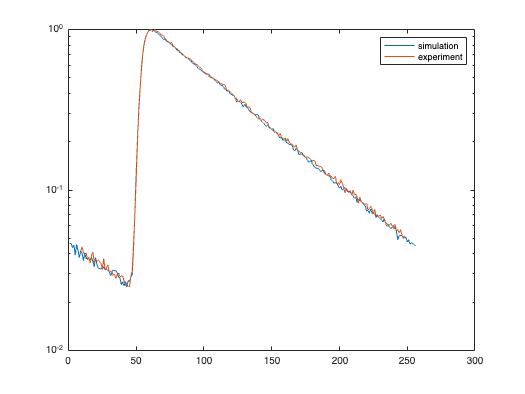

load(SaveName)
figure
% semilogy(n_final)

n_final=n_final+backcorr;
% hold on
semilogy(n_final/(max(n_final)))

hold on
semilogy(n_exp_ACh/max(n_exp_ACh))
legend('simulation','experiment')


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256

lft_steps =     0.0488    0.0977    0.1465    0.1953    0.2441    0.2930    0.3418    0.3906    0.4395    0.4883    0.5371    0.5859    0.6348    0.6836    0.7324    0.7812    0.8301    0.8789    0.9277    0.9766    1.0254    1.0742    1.1230    1.1719    1.2207    1.2695    1.3184    1.3672    1.4160    1.4648    1.5137    1.5625    1.6113    1.6602    1.7090    1.7578    1.8066    1.8555    1.9043    1.9531    2.0020    2.0508    2.0996    2.1484    2.1973    2.2461    2.2949    2.3438    2.3926    2.4414


weight_n_lft=lft_steps.*n_final(range(1):range(2));
empirical_lft_PKA=sum(weight_n_lft)/sum(n_final(range(1):range(2)))

empirical_lft_PKA = 4.6365


% from the fitted curve: empirical_lft_ACh_curve = 5.1776
% so the simulation should be good.


% Now do the real simulation, for real simulaition, for autofluorescence should have already include the dark count and SHG term
% So I'll use the population without SHG, and add no dark count to the
% simulated sample.

% first start with no autofluorescence, no after pulse
% use photoncount from the ROI for simulation

DC=0;
AF=0;
afterpulse=0;
mkdir('ACh')
mkdir('baseline')

for i=1:50
    SaveName=['ACh/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:50
    SaveName=['baseline/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];

for i=1:50
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:50
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 4.6356

mean(simulated_lft_baseline)

ans = 4.6350

% then add afterpulse as 0.8% of the total
DC=0;
AF=0;
afterpulse=0.008;
mkdir('ACh_afterpulse')
mkdir('baseline_afterpulse')

for i=1:50
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:50
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% % load the simulated data, calculate the lifetimes
% simulated_lft_ACh=[];
% simulated_lft_baseline=[];
% lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
% 
% for i=1:50
%     SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
%     load(SaveName)
% %     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
%     weight_n_lft=lft_steps.*n_final(range(1):range(2));
%     empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
%     simulated_lft_ACh(i)=empirical_lft_ACh;
% end
% 
% for i=1:50
%     SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
%     load(SaveName)
% %     n_final=n_final+backcorr_baseline*(photoncount_baseline/samplesize_baseline);
%     weight_n_lft=lft_steps.*n_final(range(1):range(2));
%     empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
%     simulated_lft_baseline(i)=empirical_lft_baseline;
% end

% then add autofluorescence, based on the ROIsize
DC=0;
AF=round(20000*ROIsize_ACh/(128*128))

AF = 1472

afterpulse=0.008;
mkdir('ACh_afterpulse_AF')
mkdir('baseline_afterpulse_AF')


for i=1:50
    SaveName=['ACh_afterpulse_AF/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:50
    SaveName=['baseline_afterpulse_AF/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% % load the simulated data, calculate the lifetimes
% simulated_lft_ACh=[];
% simulated_lft_baseline=[];
% 
% for i=1:50
%     SaveName=['ACh_afterpulse_AF/',num2str(i),'.mat'];
%     load(SaveName)
% %     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
%     weight_n_lft=lft_steps(range(1):range(2)).*n_final(range(1):range(2));
%     empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
%     simulated_lft_ACh(i)=empirical_lft_ACh;
% end
% 
% for i=1:50
%     SaveName=['baseline_afterpulse_AF/',num2str(i),'.mat'];
%     load(SaveName)
% %     n_final=n_final+backcorr_baseline*(photoncount_baseline/samplesize_baseline);
%     weight_n_lft=lft_steps(range(1):range(2)).*n_final(range(1):range(2));
%     empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
%     simulated_lft_baseline(i)=empirical_lft_baseline;
% end


% load('autofluorescence.mat')
% AF=20000;
% n_norm=conv_n_final/sum(conv_n_final)
% figure
% semilogy(n_norm)
% 
% n_ACh=n_norm*photoncount_ACh+AutoFluo0917*AF*ROIsize_ACh/(128*128)+(zeros(1,256)+backcorr_ratio*photoncount_ACh)
% figure
% semilogy(n_ACh)
% 
% n_baseline=n_norm*photoncount_baseline+AutoFluo0917*AF*ROIsize_baseline/(128*128)+(zeros(1,256)+backcorr_ratio*photoncount_baseline)
% figure
% semilogy(n_baseline)

% % empirical_lft_ACh = 5.1762
% weight_n_lft=lft_steps(range(1):range(2)).*n_ACh(range(1):range(2));
% empiricallft_ACh=sum(weight_n_lft)/sum(n_ACh(range(1):range(2)))
% 
% % empirical_lft_baseline = 5.0480
% weight_n_lft=lft_steps(range(1):range(2)).*n_baseline(range(1):range(2));
% empiricallft_baseline=sum(weight_n_lft)/sum(n_baseline(range(1):range(2)))